# Simulation on Cyclic Casual Discovery

SIMULATION study showing where harmonic flow excles in capturing recurrent cyclic interactions in a netework with 1-cycle while other causal models struggle. The  simulations are published in  

Chung, M.K., Anand, D.V., El-Yaagoubi, A.B., Jung, J.-H., Qiu, A., Ombao, H. 2026, Causality as a minimum energy principle, [IEEE Engineering in Medicine and Biology Society (EMBC)](https://embc.embs.org/2026/) pages 1-5. 

(C) 2026 Moo K. Chung, 

University of Wisconsin-Madison

### Ground Truth 

Building Directed Cyclic Graph (DCG): a directed graph that contains one or more cycles. We build cycle-only ground truth with 4-nodes indexed as 1, 2, 3 and 4. We then add two additional nodes 5 and 6 and connect node 5 to node 2, and node 6 to node 4 

clear; clc; 
Nodes = [cos((0:3)'*2*pi/4) sin((0:3)'*2*pi/4)];  
Edges = [1 2; 2 3; 3 4; 4 1];
X     = [2; 3; 3; 2];   % edge flow strength, edges are indexed following 'Edges'.

Nodes = [Nodes;  
         0   1.8;  % node 5 above node 2
         0  0.2];  % node 6 below node 4

% 
Edges = [Edges;
         2 5;      % edge from 2 -> 5
         6 4];     % edge from 6 -> 4

We then assign an edge flow X along the edge directions and vary the strength of the circulation by attenuating the magnitudes of the remaining edge flows. Subsequently, we simulate random edge flows using a vector autoregressive model with X as the ground truth, and obtain noisy observed node time series Z.

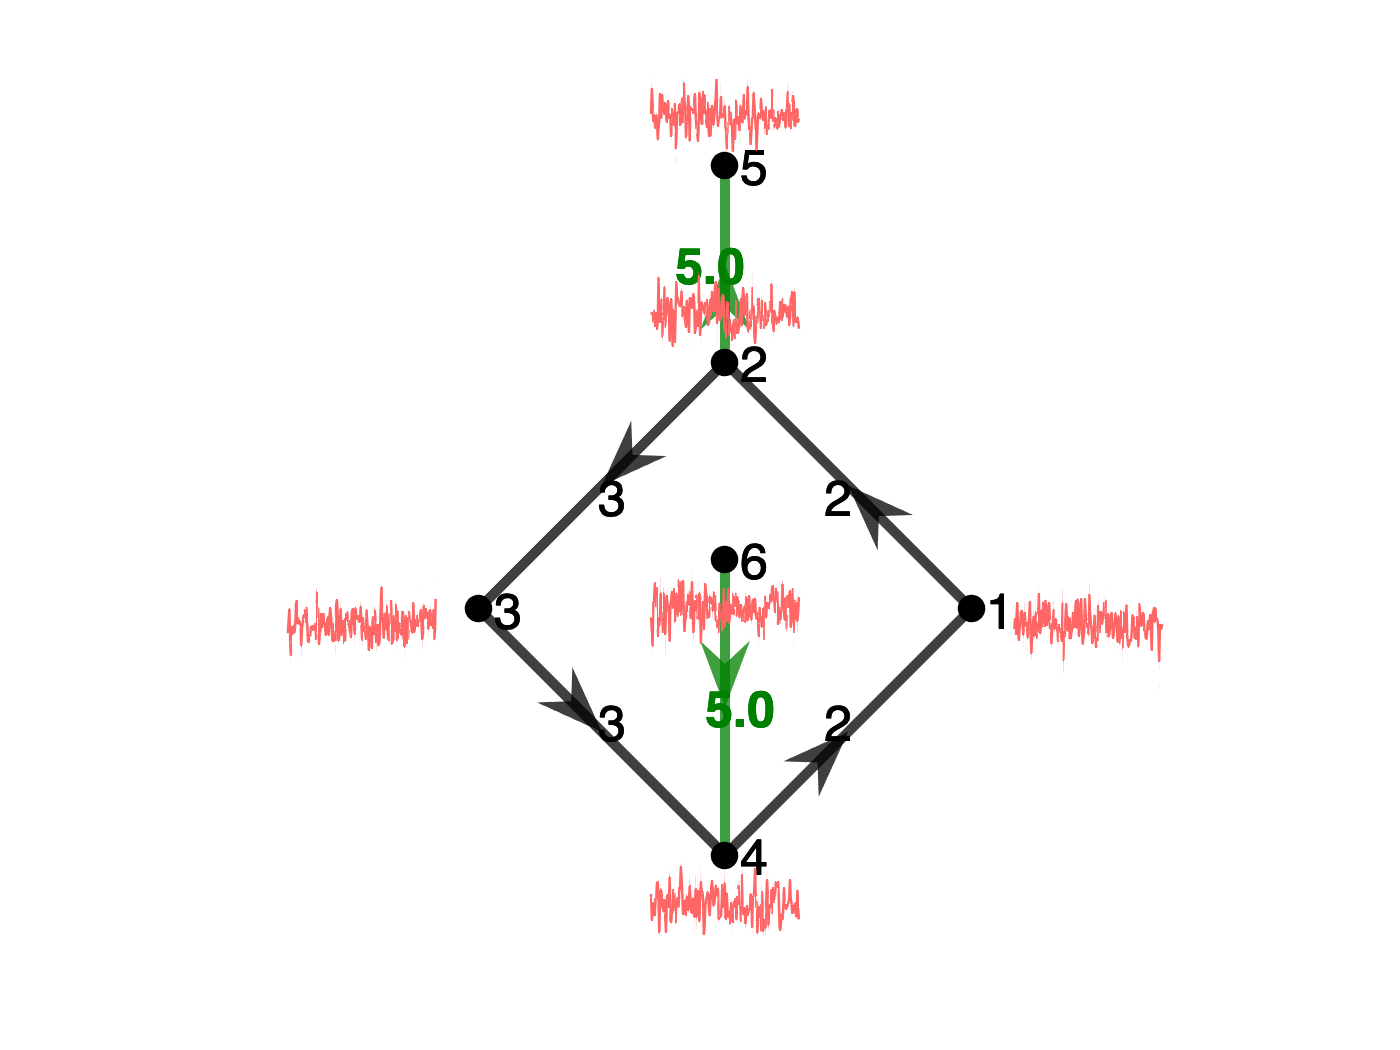

%X = [X; 0; 0];      % Only circulation
%X = [X; 0.1; 0.1];   % strong circulation
X = [X; 5; 5];      % weak circualtion
%X = [X; 100; 100];  % super weak circualtion
figure;  graph_directed_plot(Nodes, Edges, X);
Z= VAR_graph(Edges, X, 4,1);
graph_directed_plot(Nodes, Edges, X);
graph_overlay_timeseries(Nodes, Z)

In the simulation, the ground truth is a cyclic structure encoded in the connectivity matrix, and the goal is to assess whether the proposed method can accurately recover the underlying cyclic flow.

X_truth = [2; 3; 3; 2; 0; 0]'; %ground truth edge flow
C_truth = graph_edge2matrix(Edges, X_truth)

C_truth =      0     2     0    -2     0     0
    -2     0     3     0     0     0
     0    -3     0     3     0     0
     2     0    -3     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


To perform random simulations, we first generate random time series a priori and save them, so that exactly the same realizations are used across all methods. This avoids feeding different time series to different methods and ensures a fair comparison. For reproducibility, we stored the simulation results as **simulationZ_weakcirculation.mat** and **simulationZ_strongcirculation.mat** for weak and strong circulation regimes.

noise_levels = [0.1, 1, 10];
Na = numel(noise_levels);
nTrials = 100; %10 trials for faster performance. change it to 100 for publication. 

for a = 1:Na
    sigma = noise_levels(a);  
    for t = 1:nTrials
        Z = VAR_graph(Edges, X, 4, sigma);     % generate one random realization
        Zall(:,:,a,t) = Z;                     % store [T x K x Na x nTrials]
    end
end

%save simulationZ_weakcirculation Zall noise_levels Na nTrials

### Granger Causality

The implementation follows linear Granger causality within a vector autoregressive (VAR) framework, where the model order is selected using information criteria and directional dependence is quantified via residual-based variance comparisons following Geweke (1982):

Geweke, J. Measurement of linear dependence and feedback between multiple time series. *Journal of the American statistical association* 77 (1982): 304-313.

load simulationZ_weakcirculation.mat

nTrials=100; %%10 trials for faster performance. Change to 100 for publication.
% Cosine similarity for Granger causality
cos_gc = zeros(Na, nTrials);


for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);                           % stored as [K x T]
        % VAR_fit expects X as [N x T] = [nodes x time]
        [A_est, X_pred, GC_matrix, P] = VAR_fit(Z);  % Convert p-values to connectivity strength, 
                                                     % Smaller p-value = stronger evidence of Granger causality
        What = 1 - GC_matrix;                        
        scG = VAR_score(What, C_truth);
        cos_gc(a,t) = scG.cosine;
    end
end

mGC = mean(cos_gc, 2, 'omitnan');
sGC = std(cos_gc, 0, 2, 'omitnan');

disp(table(noise_levels(:), mGC, sGC, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.29737      0.085653 
       1      0.30001      0.074312 
      10      0.31486      0.078792 



### Nonlinear Structural Equation Model (SEM)

The function **SEM_nonlinear** fits, for each node $X_j$, a nonlinear additive regression model using all other variables as predictors:


$$X_j = f_j(X_{-j}) + e_j, \qquad j=1,\dots,p,$$


where $X_{-j}$ denotes all variables except $X_j$, and $f_j$ is approximated by a **Generalized Additive Model (GAM)** fitted using the built-in Matlab function **fitrgam**. Suppose the data matrix is


$$Z = [X_1,\dots,X_p] \in \mathbb{R}^{n \times p}$$


where each column is a variable and each row is an observation. For a fixed node $X_j$, the code takes column $j$ as the response variable and uses all columns of $Z$ as predictors, except that the $j$-th predictor column is set to zero so that $X_j$ is not used to predict itself. Then **fitrgam **fits a nonlinear regression model


$$X_j = f_j(X_1,\dots,X_{j-1},X_{j+1},\dots,X_p).$$
 

GAM approximates the regression function as a sum of one-dimensional nonlinear functions of each predictor. For predicting $X_j$, it fits a model of the form


$$\hat{f}_j(X_1,\dots,X_{j-1},X_{j+1},\dots,X_p) =\beta_0 + \sum_{i \neq j} g_i(X_i),$$


where each $g_i(\cdot)$ is a *basis function* estimated from the data. This model is also known a **Causal Additive Model** (CAM) in causal inference introduced by Bühlmann, P., Peters, J. and Ernest., J., 2014 [CAM: Causal additive models, high-dimensional order search and penalized regression](https://projecteuclid.org/journalArticle/Download?urlId=10.1214%2F14-AOS1260), Annals of Statistics 42: 2526-2556.

After fitting the model for node $j$, we denote the fitted function by


$$\widehat{X}_j(t) = \hat{f}_j\bigl(X_1(t),\dots,X_{j-1}(t),X_{j+1}(t),\dots,X_p(t)\bigr).$$


After fitting the model for node $j$, we computes the prediction error


$$\mathrm{MSE}_0 = \frac{1}{n}\sum_{t=1}^n \bigl(X_j(t)-\widehat{X}_j(t)\bigr)^2.$$


Note $\mathrm{MSE}_0$ only quantifies how well the function $\hat{f}_j$ predicts $X_j$ using all variables jointly, but it does not tell us which variables are responsible for this prediction accuracy. Therefore, $\mathrm{MSE}_0$ alone cannot be used to infer directed relationships $X_i \to X_j$. To isolate the effect of $X_i$, we must compare the prediction error before and after removing the information carried by $X_i$. We quantify the contribution of each predictor using **Permutation Importance, i**ntroduced in Breiman, L. 2001,[ Random forests](https://link.springer.com/article/10.1023/a:1010933404324). *Machine learning* 45:5-32. 

To assess the contribution of a specific variable $X_i$, we remove the information carried by $X_i$ by randomly permuting its values across samples, while keeping all other predictors unchanged. This breaks the association between $X_i$ and $X_j$ without altering the fitted model.

Let $\widehat{X}_j^{(i)}(t)$ denote the predictions obtained after permuting $X_i$. The corresponding prediction error is


$$\mathrm{MSE}_1^{(i \to j)} = \frac{1}{n}\sum_{t=1}^n \bigl(X_j(t)-\widehat{X}_j^{(i)}(t)\bigr)^2.$$


The importance of $X_i$ for predicting $X_j$ is then defined as


$$W_{ij} = \mathrm{MSE}_1^{(i \to j)} - \mathrm{MSE}_0,$$


which measures how much the prediction error increases when the information in $X_i$ is disrupted. If permuting $X_i$ leads to a large increase in error, then $X_i$ plays an important role in predicting $X_j$. If the change is small, then $X_i$ contributes little to the prediction. Repeating this procedure for all pairs $(i,j)$ yields a weighted directed matrix $W = (W_{ij})$, where larger values indicate stronger nonlinear predictive contribution from $X_i$ to $X_j$. However, a single permutation can introduce variability due to randomness in the shuffling. To obtain a more stable estimate, the permutation step is typically repeated multiple times and averaged. In the current implementation,  the importance is estimated using a single permutation for a faster estimate. 

Contribution: Although the individual components are well established, their combination in nonlinear SEM is not standard. In particular, using permutation importance to extract a directed dependency matrix from node-wise nonlinear SEM fits is novel. This provides a simple, scalable, and model-agnostic way to quantify directed nonlinear influence, offering an alternative to traditional structure learning methods.

load simulationZ_weakcirculation.mat

nTrials=100; %%10 trials for faster performance. Change to 100 for publication.
%Cosine similarity added
cos_nonlinSEM = zeros(Na, nTrials);
%Will take a while
for a = 1:Na
    for t = 1:nTrials
        Z=Zall(:,:,a,t);                      % [T x K] from simulator
        out = SEM_nonlinear(Z.');             % out.W_inst is [K x K], i -> j
        scT = VAR_score(out.W_inst, C_truth);
        cos_nonlinSEM(a,t) = scT.cosine;         
    end
end

mSEMnl = mean(cos_nonlinSEM, 2, 'omitnan');
sSEMnl = std(cos_nonlinSEM, 0, 2, 'omitnan');

disp(table(noise_levels(:), mSEMnl, sSEMnl, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.37625      0.039208 
       1      0.38071      0.042476 
      10       0.3694      0.035976 



### Transfer Entropy

Transfer entropy was proposed in 

Schreiber, T.,  [Measuring information transfer.](https://journals.aps.org/prl/pdf/10.1103/PhysRevLett.85.461?casa_token=CEyrmmEH7hwAAAAA%3AqoVodIP5Eu7IfpfeUTIqqEB-jVK0X4-LjMeA0o2Yx9fihWYCEWPK71OWkw2oj0e7SoElXF9gbnqFOYI) *Physical review letters* 85.2 (2000): 461.

The transfer entropy is defined trhough *mutual information*. Let $I(A;B \mid C)$ denotes the conditional mutual information between random variables $A$ and $B$ given $C$. It measures how much information $A$ provides about $B$ after the effect of $C$ has already been taken into account. It quantifies the remaining statistical dependence between $A$ and $B$ conditional on $C$. The definition is


$$I(A;B \mid C)=\sum_{a,b,c}P(a,b,c)\log \frac{P(a,b \mid c)}{P(a \mid c)\,P(b \mid c)}.$$


The term inside the logarithm compares the joint conditional distribution $P(a,b\mid c)$ with the product $P(a\mid c)P(b\mid c)$. If $A$ and $B$ are conditionally independent given $C$, then $P(a,b\mid c)=P(a\mid c)P(b\mid c),$ so the ratio is $1$, the logarithm is $0$, and hence $I(A;B\mid C)=0.$ Therefore, $I(A;B\mid C)$ is zero exactly when $A$ and $B$ share no additional information once $C$ is known, and it is positive when knowledge of $A$ reduces the uncertainty of $B$ beyond what is explained by $C$ alone.

*Transfer entropy* measures how much knowing the past of one variable helps predict the present of another variable beyond what is already explained by the target’s own past. For two node time series at $i$ and $j$, the transfer entropy from $i$ to $j$ is defined as


$$\mathrm{TE}_{i \to j} = I\big(X_i(t-1); X_j(t)\mid X_j(t-1)\big),$$


which is the conditional mutual information between the driver past $X_i(t-1)$ and the target present $X_j(t)$, conditioned on the target past $X_j(t-1)$. This is precisely Schreiber’s original idea specialized to a first-order Markov setting. Intuitively, if the past of node i provides no extra information about node $j$ once node $j$’s own past is already known, then $\mathrm{TE}_{i\to j}=0$. If node $i$’s past improves prediction of node $j$, then $\mathrm{TE}_{i\to j}>0$. The asymmetry is important: in general,

$\mathrm{TE}_{i\to j} \neq \mathrm{TE}_{j\to i}$, so TE is directional.

Conceptually, transfer entropy is more general than Granger causality because it is based on information theory rather than linear regression. Granger causality asks whether past $X_i$ improves linear prediction of $X_j$, whereas transfer entropy asks whether past $X_i$ improves prediction in an information-theoretic sense, potentially capturing nonlinear dependencies after discretization. 

Advantages: Mutual information can be applied to any type of data (e.g., genetic data such as SNP, categorical, ordinal, binary, counts) as long as a joint probability distribution can be defined. The flexibility of mutual information in handling arbitrary discrete variables makes it a powerful and model-free measure of statistical dependence.

Implementation: The function **TE** is implmented by first discretizing each time series into quantile bins. If $Z\in \mathbb{R}^{K\times T}$, then each node is converted into a discrete sequence with values in $\{1,\dots,\texttt{nBins}\}$. This is done by cutting each marginal time series into four quantile-based bins, so each bin contains roughly equal numbers of observations. After discretization, for every ordered pair (i,j), the code forms three aligned sequences:

$x_0 = X_i(t-1), \qquad y_0 = X_j(t-1), \qquad y = X_j(t)$,

with lag 1. It then estimates the joint histogram $P(y,y_0,x_0)$, and the corresponding marginals $P(y_0,x_0), P(y,y_0), P(y_0)$. Using these, **TE** computes


$$\mathrm{TE}_{i\to j} = \sum_{y,y_0,x_0} P(y,y_0,x_0) \log \frac{P(y\mid y_0,x_0)}{P(y\mid y_0)}.$$


This is exactly the discrete conditional mutual information formulation. The ratio inside the logarithm compares two predictive distributions: $P(y\mid y_0),$ which uses only the target’s own past, and $P(y\mid y_0,x_0),$ which additionally uses the driver’s past. If adding $x_0$ changes the predictive distribution substantially, then the log-ratio is large and the TE increases. So TE quantifies the reduction in uncertainty about $X_j(t)$ obtained by adding $X_i(t-1)$ to the predictor set. The matrix output **out.TE** is the full directed TE matrix, where entry $(i,j)$ corresponds to $i \to j$. The diagonal is set to zero because self-transfer is not considered. 

Sampling bias: The discrete estimatation of transfer entropy is known to exhibit a positive bias in finite samples. Even when two variables are statistically independent, the empirical estimate of transfer entropy is typically nonzero due to sampling variability in the estimated joint distribution. To mitigate this effect, we employ a bias-correction based on a shuffled null model. For each ordered pair $(i,j)$, let $\widehat{\mathrm{TE}}_{i \to j}$ denote the observed transfer entropy computed from the original data. To estimate the bias, we construct a null distribution by destroying the temporal dependence between the driver and the target while preserving marginal distributions. Specifically, we randomly permute the driver time series $X_i(t-1)$ to obtain a shuffled sequence $X_i^{(s)}(t-1)$, while keeping $X_j(t)$ and $X_j(t-1)$ unchanged. This removes any directed influence from $i$ to $j$ but retains the marginal statistics of each variable. We repeat this procedure $S$ times and compute the corresponding null transfer entropy values


$$\widehat{\mathrm{TE}}_{i \to j}^{(s)}, \quad s = 1,\dots,S.$$


The expected bias is then approximated by the sample mean


$$\mathbb{E}_{\mathrm{null}}\big[\widehat{\mathrm{TE}}_{i \to j}\big]\approx\frac{1}{S} \sum_{s=1}^S \widehat{\mathrm{TE}}_{i \to j}^{(s)}.$$


The bias-corrected transfer entropy is defined as


$$\widehat{\mathrm{TE}}^{\mathrm{corr}}_{i \to j}=\widehat{\mathrm{TE}}_{i \to j}-\frac{1}{S} \sum_{s=1}^S \widehat{\mathrm{TE}}_{i \to j}^{(s)}.$$


This correction removes the spurious contribution due to finite-sample effects and yields a more reliable estimate of directed information transfer. If there is no true causal influence from $i$ to $j$, the corrected estimate tends to be close to zero, whereas genuine directed interactions remain positive after correction.

load simulationZ_weakcirculation.mat

nTrials=100; %%10 trials for faster performance. Change to 100 for publication.
% Cosine similarity for Transfer Entropy
cos_te = zeros(Na, nTrials);

% Will take a while
for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);       % [K x T] from stored simulator
        out = TE(Z);             % out.TE are [K x K], i -> j
        scT = VAR_score(out.connectivity, C_truth);   % use bias-corrected TE
        cos_te(a,t) = scT.cosine;          
    end
end

mTE = mean(cos_te, 2, 'omitnan');
sTE = std(cos_te, 0, 2, 'omitnan');

disp(table(noise_levels(:), mTE, sTE, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.36666       0.13606 
       1      0.37086       0.13547 
      10      0.39833       0.13923 



### Cyclic Causal Discovery (CCD)

CCD here is based on 

Let $Z=[Z_1,\dots,Z_K]\in\mathbb{R}^{T\times K}$ denote the observed variables, where $T$ is the number of samples and $K$ is the number of variables.** Richardson’s Cyclic Causal Discovery (CCD) algorithm** aims to recover causal structure in the presence of feedback (cycles) by exploiting conditional independence relations. The method proceeds in four steps. 

#### **1) 1-Skeleton Extraction** 

It estimates an undirected skeleton by removing edges $(i,j)$ whenever $Z_i$ and $Z_j$ are **conditionally independent** over seperating set $S$, which is denoted as SepSet{i,j} in the code. 


$$Z_i \perp Z_j \mid S.$$
 

Simple Pearson correlation cannot distinguish direct relationships from indirect or spurious ones. Instead of testing whether $Z_i$ and $Z_j$ are directly correlated, we tests whether they are still related after removing the influence of variables in $S$. This is tested through the sample partial correlation between $Z_i$ and $Z_j$ given the variables in $S$. If the partial correlation is close to zero, then $Z_i$ and $Z_j$ are treated as conditionally independent given $S$ (under Gaussian assumption). Note if $S=\emptyset$, then the test reduces to the ordinary Pearson correlation. The partial correlation can be computed using the sample covariance matrix $\Sigma$ of $Z$ (equivalently this can be done using samaple correlation matrix). Let $\Sigma_{ijS}$ denote the submatrix indexed by the variables $\{i,j\} \cup S$. Define $P = (P_{ij}) =  \Sigma_{ijS}^{-1}.$ The **inverse covariance matrix** encodes conditional dependencies: zeros in $P$ correspond to conditional independence. The partial correlation between $Z_i$ and $Z_j$ given $S$ is computed as


$$\rho_{ij \mid S} = -\frac{P_{12}}{\sqrt{P_{11} P_{22}}}.$$


If $\rho_{ij \mid S} \approx 0$, then $Z_i$ and $Z_j$ are treated as conditionally independent, and the edge $(i,j)$ is removed.  

The algorithm then extracts the 1-skeleton by systematically applying this test across all pairs of variables. Starting from a fully connected undirected graph, for each pair $(i,j)$ the method searches over conditioning sets $S$ of increasing size $|S|$, where $S \subset (N_i \cup N_j)\setminus\{i,j\}$ and $N_i$ denotes the current neighbors of node $i$. For each candidate set $S$, the partial correlation $\rho_{ij\mid S}$ is computed and converted into a $p$-value. If there exists at least one set $S$ such that $p_{ij\mid S} > \alpha$ (currently set at 0.01), then $Z_i$ and $Z_j$ are treated as conditionally independent given $S$, and the edge $(i,j)$ is removed. This procedure is repeated iteratively for all pairs and all conditioning set sizes until no further edges can be removed. The resulting adjacency matrix $A=(A_{ij})$ defines an undirected graph, called the **skeleton**, which retains only those edges that cannot be explained away by conditional independence.

Limitation of this approach is its reliance on the inversion of covariance (or correlation) submatrices, which can become unstable in the presence of strong correlations or limited sample size. 

1) When $Z_i$ are highly correlated, $\Sigma$ becomes nearly singular, and its inverse is numerically unstable. This leads to unreliable estimates of $\rho_{ij\mid S}$ and consequently unstable $p$-values for the conditional independence test. This issue is particularly severe in high-dimensional settings where $T \ll K,$or when strong multicollinearity exists among variables. In such cases, even small perturbations in the data can lead to large fluctuations in the inverse matrix, resulting in inconsistent edge removal decisions. Furthermore, as the size of the conditioning set $|S|$ increases, the dimensionality of $\Sigma_I, \quad I=\{i,j\}\cup S,$ grows, exacerbating the instability and reducing statistical power. This can lead to both false positives (retaining spurious edges) and false negatives (removing true edges). Thus, the method suffers from the fundamental limitation in this particular simulation. 

2) In dense cyclic regime, conditional independences become extremely rare. When many feedback loops are present, almost every variable influences every other variable through multiple paths. As a result, for most pairs $(i,j)$, there is no sepearting set $S$ such that

$Z_i \perp Z_j \mid S$. Without these conditional independences, the entire constraint-based framework (including cyclic-SCM) loses its signal, because skeleton extraction depends on removing edges based on such tests. In the extreme dense regime, the skeleton becomes nearly complete. This is what we often observe in rs-fMRI brain networks. 

#### 2) Collider Detection (ad-hoc method) 

The second step introduces directionality into the undirected graph obtained above. The algorithm identifies colliders. A collider is a fork in a directed graph having the form $i \to k \leftarrow j$ (fork structure). In this case, $k$ is called a collider because the two incoming edges collide at $k$. If $i$ and $j$ are both adjacent to $k$, but $i$ and $j$ are not adjacent, then $(i,k,j)$ is an unshielded triple. If $k\notin \mathrm{SepSet}(i,j)$, the triple is oriented as $i \to k \leftarrow j.$

After the undirected skeleton $A$ has been estimated, the algorithm examines each node $k$ and its current neighbors


$$N_k = \{i : A_{ik}=1\}.$$


If $k$ has at least two neighbors, the algorithm considers every unordered pair $(i,j)$ from $N_k$. For each such pair, it checks whether $i$ and $j$ are themselves adjacent. If 


$$A_{ik}=1, \qquad A_{jk}=1, \qquad A_{ij}=0,$$


then $(i,k,j)$ forms an unshielded triple. The algorithm then consults the separating set obtained during skeleton extraction. If


$$k \notin \mathrm{SepSet}(i,j),$$


the triple is oriented as a collider, $i \to k \leftarrow j.$

In the code, this is implemented by setting

orient(i,k) = 1, orient(j,k) = 1.

#### 3) Propagation Rule

After Collider Detection, only a subset of edges are oriented. We apply additional Propagation Rules to orient as many of the remaining undirected edges as possible while maintaining consistency with the conditional independence structure. After collider detection, only edges involved in unshielded triples with identifiable v-structures are oriented, while many edges remain undirected because local conditional independence information is insufficient to determine their direction. The propagation rules resolve these remaining ambiguities by enforcing global consistency with already oriented edges such that any newly assigned direction does not introduce a collider or dependency that contradicts the previously identified separating sets SepSet}(i,j). These rules propagate directions along existing paths and prevent the creation of unsupported v-structures, thereby extending locally identified orientations to a larger portion of the graph while remaining consistent with the conditional independence structure. 

Limitation of the propagation step is that it enforces global consistency with estimated conditional independence relations, which are statistical in nature and may not accurately reflect the true physical or causal mechanisms, particularly in the presence of noise, latent variables, or model misspecification.

#### 4) Cycle Identification

Richardson (1996) allows cyclic structures but does not provide a simple or explicit procedure for enumerating cycles; the resulting representation (PAG) encodes cyclic equivalence classes implicitly. Thus, in Step 4, we replace this step with a standard graph-theoretic cycle detection based on strongly connected components (Tarjan, 1972) and depth-first search enumeration (Johnson, 1975):

Tarjan, R. 1972, [Depth-first search and linear graph algorithms](https://epubs.siam.org/doi/pdf/10.1137/0201010?casa_token=7V90Kbkh3xUAAAAA:CY6g88dii0l-LjJ7q_FCZXGUMxo3c01K33kJEW6_gSkITaLYl9gXbnT2v3G3Sa8GII5boOlzif4Z). SIAM journal on computing 1:146-160.

Johnson, D.B. 1975, [Finding all the elementary circuits of a directed graph](https://epubs.siam.org/doi/pdf/10.1137/0204007?casa_token=IuUAdZ3NrvsAAAAA:VT4xjZq8X1TQ6MOsu4nX3TtW8qPdJj1yHFmcFj4L5qjj8QnKS6QyKaC1ccNj3RGVhDLLXrHaBA3b). SIAM Journal on Computing 4:77-84.

This provides an explicit and computationally efficient way to identify directed cycles in the estimated graph. After the orientation step, the directed graph is represented by the adjacency matrix $G = (G_{ij})$, where $G_{ij}=1$ indicates a directed edge $i \to j$. Cycles are identified in two stages. 

First, strongly connected components (SCCs) are computed using Tarjan’s algorithm. A subset of nodes $\mathcal{C} \subset \{1,\dots,K\}$ is a strongly connected component if for every pair $i,j \in \mathcal{C}$ there exist directed paths $$
i \to \cdots \to j
$$ and $j \to \cdots \to i$. Any SCC with $|\mathcal{C}| > 1$ necessarily contains at least one directed cycle, providing a coarse but efficient localization of cyclic structure.

Second, within each SCC, explicit cycles are enumerated using depth-first search (DFS) following Johnson’s algorithm. Starting from a node $s$, the algorithm recursively explores all directed paths $s \to \cdots \to s$ without revisiting nodes, thereby identifying all simple cycles (elementary circuits). Each detected cycle is a sequence of nodes $(i_1, i_2, \dots, i_m)$ such that $i_1 \to i_2 \to \cdots \to i_m \to i_1.$ Together, SCC decomposition restricts the search space to cyclic regions, while DFS-based enumeration provides an explicit list of directed cycles in the estimated graph.

Limitation: In contrast to very involing cycle identification steps in CCD, [harmonic flows](https://arxiv.org/pdf/2603.29843) (Chung et al., 2026) provide a scalable vector space representation of cycles, i.e., $\ker (\Delta_1)$ making computation straightforward without requiring cumbersome computational steps:

Chung, M.K., Luigi M. and Aaron S. 2026 [Counterfactual Analysis of Brain Network Dynamics](https://arxiv.org/pdf/2603.29843). ISBI, pages 1-5 *arXiv preprint arXiv:2603.29843*.

load simulationZ_weakcirculation.mat %This is simulation where CCD will not break. 
                     % In almost all simulatins, CCD will break up due to high multicorrelinarity. 

nTrials=100; %%10 trials for faster performance. Change to 100 for publication.
cos_ccd = zeros(Na, nTrials);

% Will take a while
for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);                    % stored as [K x T]
        out = CCD_R(Z.');              % transpose to [T x K] 
        What = out.connectivity;              % [K x K]
        What(1:size(What,1)+1:end) = 0;       % remove self-loops
        
        scT = VAR_score(What, C_truth);
        cos_ccd(a,t) = scT.cosine;
    end
end

mCCD = mean(cos_ccd, 2, 'omitnan');
sCCD = std(cos_ccd, 0, 2, 'omitnan');

disp(table(noise_levels(:), mCCD, sCCD, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))  

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1       0.07546      0.15548 
       1      0.042781      0.11438 
      10      0.071808       0.1579 



### Lagged Pearson Correlation

As a simple directional baseline, we consider time-lagged Pearson correlation. Let $X \in \mathbb{R}^{T \times R}$ denote the observed multivariate time series, where $T$ is the number of time points and $R$ is the number of nodes. For a fixed lag $\ell > 0$, the time-lagged correlation from node $i$ to node $j$ is defined by correlating the signal of node $i$ at time $t$ with the signal of node $j$ at time $t+\ell$. Within a window of length $w$, this is computed as


$$\mathrm{TL}_{ij}=\mathrm{corr}\!\Big(X_i(t:t+w-1),\, X_j(t+\ell:t+w-1+\ell)\Big).$$


Because the two time series are shifted relative to one another, the resulting matrix is generally asymmetric: $\mathrm{TL}_{ij} \neq \mathrm{TL}_{ji}.$ Thus, positive lag induces a directional notion of association, in contrast to ordinary Pearson correlation, which is symmetric.

In the implementation, the time series are first standardized across time. For each sliding window, two aligned segments are extracted:


$$X_1 = X(t:t+w-1,:), \qquad X_2 = X(t+\ell:t+w-1+\ell,:),$$


and each segment is z-scored within the window. The time-lagged correlation matrix is then computed by

$A = \frac{X_1^\top X_2}{w-1},$ so that $A_{ij}$ measures the lagged correlation from node $i$ to node $j$ in that window. When only one window is used over the full time series, this yields a single asymmetric matrix summarizing directed lagged dependence. For evaluation in the present simulation, we use a fixed lag $\ell=1$ and compute the full time-lagged correlation matrix for each realization. Since the goal is to compare with the ground-truth directed connectivity matrix $C_{\mathrm{truth}}$, the estimated lagged correlation matrix is treated as a weighted directed adjacency matrix and scored using cosine similarity. This provides a simple baseline for assessing whether delayed linear association can recover the underlying cyclic structure.

Comparision against Granger and Transfer Entropy: Granger causality and transfer entropy typically outperform time-lagged correlation because they estimate **conditional, directed effects**, whereas time-lagged correlation captures only marginal propagation. However, the common criticism of Pearson-based measures largely applies to **sparse, acyclic systems**, where conditional estimation can reliably separate direct from indirect effects. In **dense or cyclic systems with strong feedback**, this distinction becomes less clear, as indirect pathways, common drivers, and multicollinearity can degrade conditional estimates, while time-lagged correlation continues to reflect the dominant propagation structure.

Time-lagged correlation is defined as $\mathrm{corr}(X_i(t-1), X_j(t)),$ which captures any statistical association between the past of node i and the present of node j. However, this association aggregates contributions from multiple sources, including direct effects i \to j, indirect paths such as i \to k \to j, and shared inputs k \to i, k \to j. As a result, time-lagged correlation conflates direct and indirect dependencies and cannot distinguish whether the observed relationship reflects a true causal interaction. In contrast, Granger causality is based on a multivariate autoregressive model $X_j(t) = \sum_{k=1}^K B_{jk} X_k(t-1) + \varepsilon_j(t),$ where each coefficient $B_{ji}$ quantifies the contribution of $X_i(t-1)$ to predicting $X_j(t)$ **after conditioning on all other variables. **This conditioning removes indirect effects and isolates direct dependencies. Similarly, transfer entropy measures the conditional mutual information$I\big(X_i(t-1); X_j(t)\mid X_j(t-1)\big),$ which quantifies the additional predictive information provided by X_i(t-1) beyond the target’s own past. Both approaches explicitly control for confounding influences and therefore provide a principled notion of directed dependence. The advantage of conditional methods is particularly evident in systems with **sparse structure**. For example, in a simple chain $i \to k \to j,$ time-lagged correlation will typically detect a spurious association between i and j, since information propagates through the intermediate node. In contrast, Granger causality and transfer entropy will correctly eliminate this indirect edge by conditioning on $k$. Similarly, in the presence of a common driver $k \to i, k \to j$ in a fork structure, time-lagged correlation will produce a false directional relationship between $i$ and $j$, whereas conditional methods can remove this effect.

From a theoretical perspective, the distinction can be understood through the relationship between covariance and the system dynamics. In a VAR(1) model:

$X(t) = B X(t-1) + \varepsilon(t),$ with $\mathbb{E}[\varepsilon(t)]=0, \; \mathrm{Cov}(\varepsilon(t))=\Sigma_\varepsilon,$ 

we define the lag-k covariance matrices as


$$\Sigma_k = \mathbb{E}[X(t) X(t-k)^\top].$$


Then th cross-covariance between present and past is given by


$$\Sigma_1 = \mathbb{E}[X(t)X(t-1)^\top] = B \Sigma_0,$$


where $\Sigma_0 = \mathbb{E}[X(t)X(t)^\top]$ is the contemporaneous covariance. This identity shows that time-lagged correlation estimates $\Sigma_1$, which is not the structural matrix $B$ itself, but rather a **transformed version of **$B$ through multiplication by $\Sigma_0$. Since $\Sigma_0$ encodes the covariance structure induced by the entire network, including indirect paths and feedback loops, the product $B\Sigma_0$ inherently aggregates contributions from multiple pathways. In particular, $\Sigma_0$ can be expanded as

$\Sigma_0 = \sum_{k=0}^\infty B^k \Sigma_\varepsilon (B^k)^\top$, so that $\Sigma_1 = B\Sigma_0 = \sum_{k=0}^\infty B^{k+1} \Sigma_\varepsilon (B^k)^\top$,

which explicitly shows that $\Sigma_1$ accumulates effects from paths of all lengths. Thus, time-lagged correlation reflects a **propagation operator** that mixes direct and indirect interactions across the network. In contrast, Granger causality aims to recover the coefficient matrix $B$ itself, which encodes direct interactions. Thus, time-lagged correlation approximates a propagation operator, while Granger causality and transfer entropy estimate conditional structural relationships.

When the system is sparse, weakly coupled, and sufficiently well-conditioned, conditional estimation is stable and accurately recovers direct edges. In such settings, Granger causality and transfer entropy outperform time-lagged correlation both in identifying correct edges and in avoiding spurious connections. However, this advantage diminishes—and can even reverse—in **dense cyclic systems with strong feedback.** In such regimes, repeated propagation along cycles induces high multicollinearity among lagged predictors, making conditional estimation unstable and ill-posed. As a result, Granger causality and transfer entropy tend to attenuate or fragment true interactions due to over-conditioning and cancellation across multiple feedback pathways. In contrast, time-lagged correlation directly reflects the lagged covariance structure, which aggregates these propagation effects into a coherent global pattern. Consequently, although it does not recover direct causal edges, it can exhibit stronger agreement with the ground truth under global similarity measures such as cosine similarity.

load simulationZ_weakcirculation.mat

nTrials=100; %%10 trials for faster performance. Change to 100 for publication.
cos_tl = zeros(Na, nTrials);

for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);                    % [K x T]
        
        lag = 1;
        X = Z.';                              % [T x K]
        winSize  = size(X,1) - lag;           % use the full valid series
        stepSize = 1;
        
        TL = TS2timelagged(X, lag, winSize, stepSize);   % [K x K x 1]
        What = TL(:,:,1);                                  % lagged correlation matrix
        
        scT = VAR_score(What, C_truth);
        cos_tl(a,t) = scT.cosine;
    end
end

mTL = mean(cos_tl, 2, 'omitnan');
sTL = std(cos_tl, 0, 2, 'omitnan');

disp(table(noise_levels(:), mTL, sTL, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'}))

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1       0.5833      0.047339 
       1      0.59597      0.044094 
      10      0.58769      0.053953 



### Harmonic Flow

Harmonic flow provides a direct representation of recurrent cyclic structure on edges and is therefore particularly suitable for the present simulation, where the ground truth is a single directed 1-cycle. It is **model agnostic**. In the Hodge decomposition, an** edge flow** $X \in \mathbb{R}^{|E|}$ is uniquely decomposed as


$$X = X_G + X_C + X_H = B_1^\top s + B_2 \phi + X_H,$$


where $X_G$ is the gradient component, $X_C$ is the curl component, and $X_H$ is the harmonic component. The harmonic flow is characterized by the constraints with boundary matrices $B_1$ and $B_2$:


$$B_1 X_H = 0, \qquad B_2^\top X_H = 0,$$


so it is simultaneously divergence-free and curl-free. In [Chung et al. (2026, ISBI)](https://arxiv.org/pdf/2603.29843), this decomposition is used to separate edge flows into directional acyclic propagation, localized triangular circulation, and global recurrent flow, with the harmonic component representing large-scale recurrent patterns that cannot be explained by node potentials or local triangular cycles .

To extract the harmonic flow, we use the 1-Hodge Laplacian


$$\Delta_1 = B_1^\top B_1 + B_2 B_2^\top$$


and evolve the edge flow under the diffusion equation


$$\frac{dX(\tau)}{d\tau} = - \Delta_1 X(\tau), \qquad X(0)=X_0.$$


The steady state satisfies $\Delta_1 X(\infty)=0,$ which implies


$$B_1 X(\infty)=0, \qquad B_2^\top X(\infty)=0,$$


and therefore the diffusion asymptotically removes the gradient and curl components while preserving only the harmonic component. Equivalently,


$$X_H = \lim_{\tau\to\infty} X(\tau).$$


This makes harmonic flow especially attractive computationally: instead of estimating a large directed graph and then performing collider detection, propagation rules, and explicit cycle enumeration, as in CCD, one directly extracts the persistent cyclic component as the equilibrium solution of a linear diffusion process.

In the present simulation, this is precisely the desired behavior. The true signal is a recurrent cycle over nodes 1, 2, 3 and 4, while the additional edges (2,5) and (6,4) are non-cyclic attachments. Under Hodge diffusion, the non-cyclic gradient-like components dissipate, while the persistent circulation remains in $X_H$. Thus, harmonic flow targets the recurrent cycle as a vector-space object rather than as a combinatorial graph pattern. This is the main reason harmonic flow is expected to outperform Granger causality, nonlinear SEM, and CCD in this simulation: those methods attempt to recover edgewise directionality from noisy node time series, whereas harmonic flow directly isolates the persistent cyclic component of the induced edge flow through the kernel of $\Delta_1$.

load simulationZ_weakcirculation.mat

for a = 1:Na
    for t = 1:nTrials
        Z = Zall(:,:,a,t);  
        lag = 1;
        TL  = TS2timelagged(Z.', lag, size(Z.',1)-lag, 1); % TL=[R x R x 1], time-lagged correlation matrix
        TLas = adj_AntiSymmetric(TL); %make asymmetric matrix into antisymmetric
        % Create 1-Skeleton from the antisymmetric matrix. The simplical complex will not have any curl. 
        S= adj2simplex(TLas,1); % Note: S = Hodge_kSkeleton(TLas, 1) perform the identical task. 
        flows = adj2edgeflow(Edges, TLas); % Extract edge flow from antisymmetric matrix along 'Edges'.
        B = PH_boundary(S); %Compute the boundary matrix
        [Yg, Yc, Yh] = Hodge_decompose_edgeflow(flows, B); % Hodge decompostion
        H = flow2matrix(Nodes, Edges, Yh); % harmonic edge flow to connectivity matrix
        scH = VAR_score(H, C_truth);   % performance score
        cos_H(a,t) = scH.cosine;
    end
end

mCCD = mean(cos_H, 2, 'omitnan');
sCCD = std(cos_H, 0, 2, 'omitnan');

disp(table(noise_levels(:), mCCD, sCCD, ...
    'VariableNames', {'Noise','MeanCosine','StdCosine'})) 

    Noise    MeanCosine    StdCosine
    _____    __________    _________

     0.1      0.63472       0.06518 
       1      0.64801      0.060609 
      10      0.63289      0.088605 

